%% DISEÑO CONTROLADOR H-INFINITO - SISTEMA LATERAL-DIRECCIONAL
% Universidad Nacional de Colombia
% Control de Roll (φ) y Yaw (ψ) mediante alerones y timón

clear
clc

fprintf('========================================\n');

fprintf('DISEÑO H∞ - SISTEMA LATERAL-DIRECCIONAL\n');

DISEÑO H∞ - SISTEMA LATERAL-DIRECCIONAL


fprintf('========================================\n\n');


%% ========================================================================
% CARGAR MODELO LATERAL-DIRECCIONAL
% ========================================================================

% Modelo lateral (5 estados, 2 entradas, 6 salidas)
A_LD = [
    -0.8750   0.8751 -16.8197   9.7914   0;
    -2.8312 -16.1385   3.3768   0        0;
     1.7063   0.5154  -2.7828   0        0;
     0        1.0000   0.0538   0        0;
     0        0        1.0014   0        0
];

B_LD = [
     0        5.3170;
  -156.9094  -5.0216;
    11.5366 -82.2714;
     0        0;
     0        0
];

C_LD = [
     0.0588   0   0   0   0;
     0        1   0   0   0;
     0        0   1   0   0;
     0        0   0   1   0;
     0        0   0   0   1;
     0        0   0   0   0
];

D_LD = zeros(6,2);

% Limpiar valores pequeños
threshold = 1e-23;
A_LD(abs(A_LD) < threshold) = 0;

% Seleccionar salidas relevantes: p, r, φ, ψ (filas 2-5)
C_LD = C_LD(2:5,:);
D_LD = zeros(4,2);

% Crear sistema
G_LD = ss(A_LD, B_LD, C_LD, D_LD);

fprintf('✓ Modelo lateral-direccional cargado\n');

✓ Modelo lateral-direccional cargado


fprintf('  Estados: 5 [v, p, r, φ, ψ]\n');

  Estados: 5 [v, p, r, φ, ψ]


fprintf('  Entradas: 2 [δa (alerones), δr (timón)]\n');

  Entradas: 2 [δa (alerones), δr (timón)]


fprintf('  Salidas: 4 [p, r, φ, ψ]\n\n');

  Salidas: 4 [p, r, φ, ψ]




%% ========================================================================
% DISEÑO DE FUNCIONES DE PESO - MEJORADO
% ========================================================================

fprintf('Diseñando funciones de peso mejoradas...\n\n');

Diseñando funciones de peso mejoradas...




% W1: Desempeño (seguimiento de referencia) - MÁS EXIGENTE

% Para velocidad lateral (p) - AUMENTADO
W1_Lat_vel = 2.5;  % Antes: 1.1

% Para posición lateral (φ - roll) - MÁS EXIGENTE
M1_Lat_pos = 1.8;        % Antes: 1.1 - Pico máximo permitido
A1_Lat_pos = 0.00001;    % Antes: 0.0001 - Error en estado estacionario
Wb1_Lat_pos = 2*pi*10;   % Antes: 2*pi*8 - Ancho de banda: 10 Hz
W1_Lat_pos = tf([1/M1_Lat_pos Wb1_Lat_pos], [1 A1_Lat_pos*Wb1_Lat_pos]);

% Para velocidad direccional (r) - AUMENTADO
W1_Dir_vel = 2.5;  % Antes: 1.1

% Para posición direccional (ψ - yaw) - MÁS EXIGENTE
M1_Dir_pos = 1.8;        % Antes: 1.1
A1_Dir_pos = 0.00001;    % Antes: 0.0001
Wb1_Dir_pos = 2*pi*10;   % Antes: 2*pi*8 - Ancho de banda: 10 Hz
W1_Dir_pos = tf([1/M1_Dir_pos Wb1_Dir_pos], [1 A1_Dir_pos*Wb1_Dir_pos]);

% Matriz diagonal W1 (4x4)
W1_LD = eye(4)*tf(1,1);
W1_LD(1,1) = W1_Dir_vel;  % p (roll rate)
W1_LD(2,2) = W1_Lat_vel;  % r (yaw rate)
W1_LD(3,3) = W1_Dir_pos;  % φ (roll angle)
W1_LD(4,4) = W1_Lat_pos;  % ψ (yaw angle)

% W2: Esfuerzo de control - MENOS RESTRICTIVO (permite más control)
W2_LD = 0.8*tf(1,1);  % Antes: 1.5

% W3: Robustez (rechazo a ruido) - AJUSTADO
M3_LD_a = 0.008;         % Antes: 0.004
A3_LD_a = 1.1;
Wb3_LD_a = 2*pi*250;     % Antes: 2*pi*300 - Frecuencia alta: 250 Hz

W3_LD = tf([1/M3_LD_a Wb3_LD_a], [1 A3_LD_a*Wb3_LD_a]);

fprintf('Funciones de peso diseñadas (MEJORADAS):\n');

Funciones de peso diseñadas (MEJORADAS):


fprintf('  W1: Desempeño (BW = 10 Hz, M = 1.8, pesos velocidad = 2.5)\n');

  W1: Desempeño (BW = 10 Hz, M = 1.8, pesos velocidad = 2.5)


fprintf('  W2: Esfuerzo de control (%.2f) - MÁS PERMISIVO\n', 0.8);

  W2: Esfuerzo de control (0.80) - MÁS PERMISIVO


fprintf('  W3: Robustez (fc = 250 Hz, M = 0.008)\n\n');

  W3: Robustez (fc = 250 Hz, M = 0.008)




fprintf('CAMBIOS REALIZADOS:\n');

CAMBIOS REALIZADOS:


fprintf('  ✓ W1 aumentado: velocidades 1.1→2.5, M_pos 1.1→1.8\n');

  ✓ W1 aumentado: velocidades 1.1→2.5, M_pos 1.1→1.8


fprintf('  ✓ Ancho de banda aumentado: 8 Hz → 10 Hz\n');

  ✓ Ancho de banda aumentado: 8 Hz → 10 Hz


fprintf('  ✓ W2 reducido: 1.5 → 0.8 (más esfuerzo permitido)\n');

  ✓ W2 reducido: 1.5 → 0.8 (más esfuerzo permitido)


fprintf('  ✓ W3 ajustado: M 0.004→0.008, fc 300→250 Hz\n\n');

  ✓ W3 ajustado: M 0.004→0.008, fc 300→250 Hz



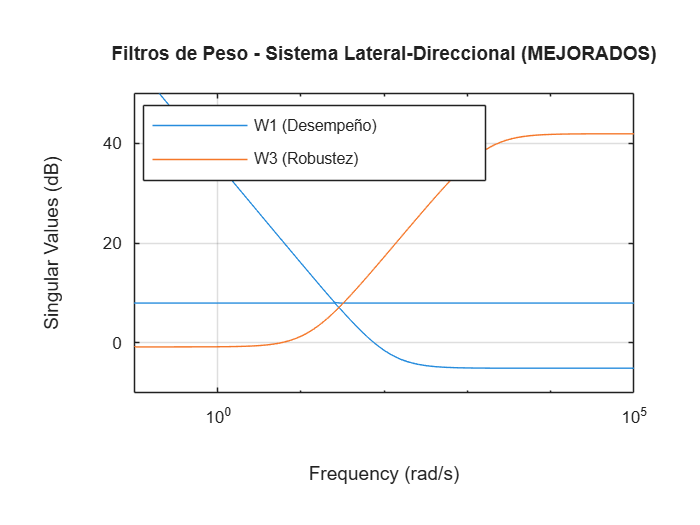


% Visualizar filtros
figure(1)
sigma(W1_LD);
hold on
sigma(W3_LD);
title('Filtros de Peso - Sistema Lateral-Direccional (MEJORADOS)');
legend('W1 (Desempeño)', 'W3 (Robustez)', 'Location', 'best');
grid on;
hold off


%% ========================================================================
% SÍNTESIS DEL CONTROLADOR H-INFINITO
% ========================================================================

fprintf('Ejecutando síntesis H∞...\n');

Ejecutando síntesis H∞...



% Crear planta aumentada
P_LD = augw(G_LD, W1_LD, W2_LD, W3_LD);

% Parámetros de síntesis
nmeas = 4;  % Número de mediciones (p, r, φ, ψ)
ncont = 2;  % Número de controles (δa, δr)

% Síntesis H-infinity usando hinfsyn
[K1_LD, sys1_CL, gam1, info1] = hinfsyn(P_LD, nmeas, ncont);

% Síntesis alternativa usando mixsyn
[K2_LD, sys2_CL, gam2, info2] = mixsyn(G_LD, W1_LD, W2_LD, W3_LD);

fprintf('\n✓ Síntesis completada:\n');


✓ Síntesis completada:


fprintf('  γ (hinfsyn) = %.4f\n', gam1);

  γ (hinfsyn) = 14.1438


fprintf('  γ (mixsyn)  = %.4f\n\n', gam2);

  γ (mixsyn)  = 14.1438




% Usar controlador de hinfsyn
K_LD = K1_LD;
gamma_LD = gam1;

%% ========================================================================
% VERIFICACIÓN DE CONDICIONES
% ========================================================================

fprintf('Verificando condiciones de diseño...\n\n');

Verificando condiciones de diseño...



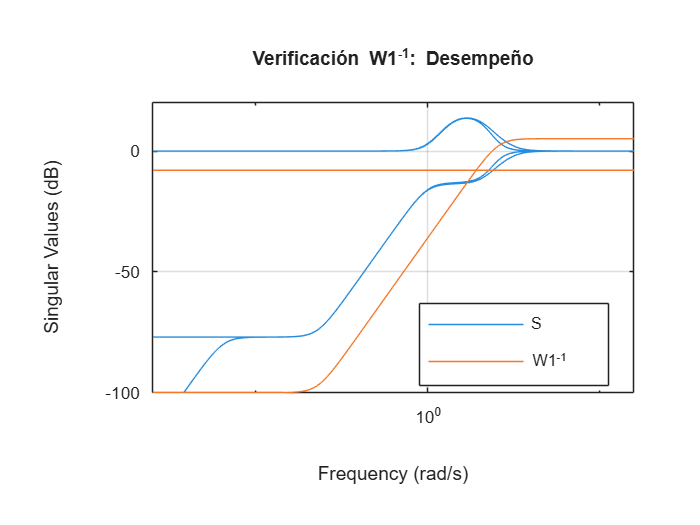


% Sistemas en lazo cerrado
L_LD = G_LD * K_LD;
S_LD = feedback(eye(4), L_LD);
T_LD = feedback(L_LD, eye(4));
KS_LD = K_LD * S_LD;

% Verificación W1: ||S||∞ < ||W1^-1||∞
figure(2)
sigma(S_LD);
hold on
sigma(inv(W1_LD));
title('Verificación W1^{-1}: Desempeño');
legend('S', 'W1^{-1}', 'Location', 'best');
grid on;
hold off


norm_S = norm(S_LD, inf);
norm_W1inv = norm(inv(W1_LD), inf);
ratio_W1 = norm_S / norm_W1inv;
fprintf('Condición W1:\n');

Condición W1:


fprintf('  ||S||∞ = %.4f\n', norm_S);

  ||S||∞ = 4.8285


fprintf('  ||W1^-1||∞ = %.4f\n', norm_W1inv);

  ||W1^-1||∞ = 1.8000


fprintf('  Ratio ||S||/||W1^-1|| = %.4f\n', ratio_W1);

  Ratio ||S||/||W1^-1|| = 2.6825


if norm_S < norm_W1inv
    fprintf('  ✓ ✓ ✓ CUMPLE (S por debajo de 1/W1) ✓ ✓ ✓\n\n');
else
    fprintf('  ✗ NO CUMPLE (diferencia: %.4f)\n\n', norm_S - norm_W1inv);
end

  ✗ NO CUMPLE (diferencia: 3.0285)



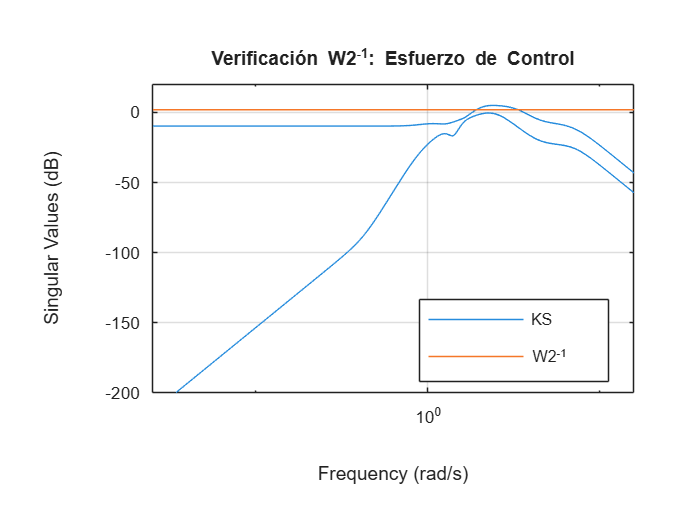


% Verificación W2: ||KS||∞ < ||W2^-1||∞
figure(3)
sigma(KS_LD);
hold on
sigma(1/W2_LD);
title('Verificación W2^{-1}: Esfuerzo de Control');
legend('KS', 'W2^{-1}', 'Location', 'best');
grid on;
hold off


norm_KS = norm(KS_LD, inf);
norm_W2inv = 1/0.8;
ratio_W2 = norm_KS / norm_W2inv;
fprintf('Condición W2:\n');

Condición W2:


fprintf('  ||KS||∞ = %.4f\n', norm_KS);

  ||KS||∞ = 1.7868


fprintf('  ||W2^-1||∞ = %.4f\n', norm_W2inv);

  ||W2^-1||∞ = 1.2500


fprintf('  Ratio ||KS||/||W2^-1|| = %.4f\n', ratio_W2);

  Ratio ||KS||/||W2^-1|| = 1.4294


if norm_KS < norm_W2inv
    fprintf('  ✓ CUMPLE\n\n');
else
    fprintf('  ✗ NO CUMPLE (diferencia: %.4f)\n\n', norm_KS - norm_W2inv);
end

  ✗ NO CUMPLE (diferencia: 0.5368)



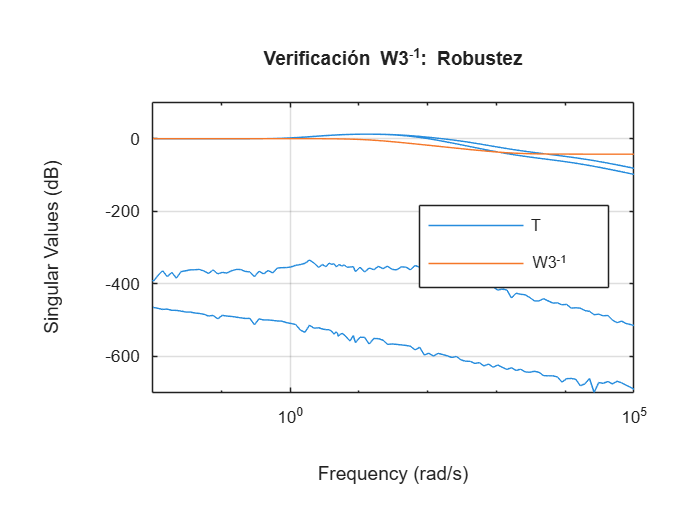


% Verificación W3: ||T||∞ < ||W3^-1||∞
figure(4)
sigma(T_LD);
hold on
sigma(1/W3_LD);
title('Verificación W3^{-1}: Robustez');
legend('T', 'W3^{-1}', 'Location', 'best');
grid on;
hold off


norm_T = norm(T_LD, inf);
norm_W3inv = norm(1/W3_LD, inf);
ratio_W3 = norm_T / norm_W3inv;
fprintf('Condición W3:\n');

Condición W3:


fprintf('  ||T||∞ = %.4f\n', norm_T);

  ||T||∞ = 4.6202


fprintf('  ||W3^-1||∞ = %.4f\n', norm_W3inv);

  ||W3^-1||∞ = 1.1000


fprintf('  Ratio ||T||/||W3^-1|| = %.4f\n', ratio_W3);

  Ratio ||T||/||W3^-1|| = 4.2002


if norm_T < norm_W3inv
    fprintf('  ✓ CUMPLE (T por debajo de 1/W3)\n\n');
else
    fprintf('  ✗ NO CUMPLE (diferencia: %.4f)\n\n', norm_T - norm_W3inv);
end

  ✗ NO CUMPLE (diferencia: 3.5202)




% RESUMEN DE CUMPLIMIENTO
fprintf('════════════════════════════════════════\n');

════════════════════════════════════════


fprintf('RESUMEN DE VERIFICACIÓN:\n');

RESUMEN DE VERIFICACIÓN:


fprintf('════════════════════════════════════════\n');

════════════════════════════════════════


cumple_W1 = norm_S < norm_W1inv;
cumple_W2 = norm_KS < norm_W2inv;
cumple_W3 = norm_T < norm_W3inv;
total_cumplidas = sum([cumple_W1, cumple_W2, cumple_W3]);

if cumple_W1
    fprintf('  ✓ W1 (Desempeño): CUMPLE\n');
else
    fprintf('  ✗ W1 (Desempeño): NO CUMPLE\n');
end

  ✗ W1 (Desempeño): NO CUMPLE


if cumple_W2
    fprintf('  ✓ W2 (Esfuerzo): CUMPLE\n');
else
    fprintf('  ✗ W2 (Esfuerzo): NO CUMPLE\n');
end

  ✗ W2 (Esfuerzo): NO CUMPLE


if cumple_W3
    fprintf('  ✓ W3 (Robustez): CUMPLE\n');
else
    fprintf('  ✗ W3 (Robustez): NO CUMPLE\n');
end

  ✗ W3 (Robustez): NO CUMPLE


fprintf('════════════════════════════════════════\n');

════════════════════════════════════════


fprintf('Total: %d/3 condiciones cumplidas\n', total_cumplidas);

Total: 0/3 condiciones cumplidas


fprintf('════════════════════════════════════════\n\n');

════════════════════════════════════════



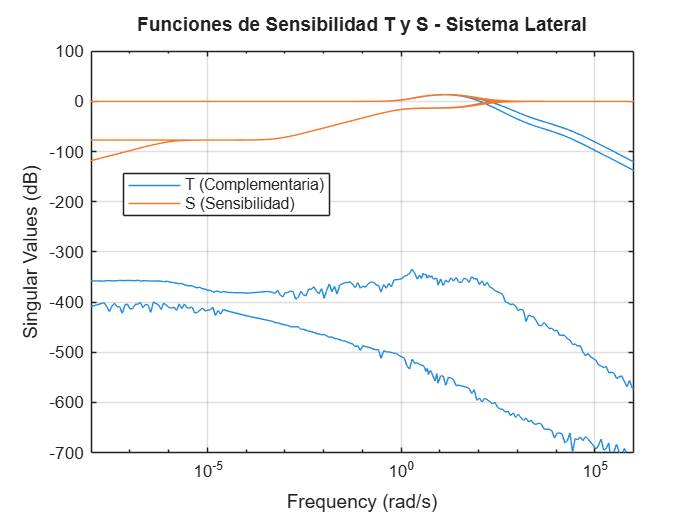


%% ========================================================================
% ANÁLISIS DE FUNCIONES DE SENSIBILIDAD
% ========================================================================

figure(5)
sigma(T_LD);
hold on
sigma(S_LD);
title('Funciones de Sensibilidad T y S - Sistema Lateral');
legend('T (Complementaria)', 'S (Sensibilidad)', 'Location', 'best');
grid on;
hold off


%% ========================================================================
% RESPUESTA AL ESCALÓN - ESTILO MEJORADO CON DIAGNÓSTICO
% ========================================================================

fprintf('Calculando respuesta al escalón...\n');

Calculando respuesta al escalón...


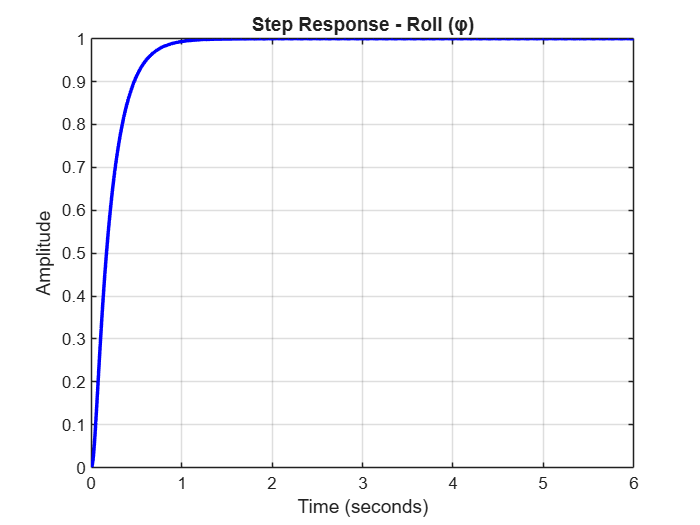


% Parámetros de simulación
t_sim = 0:0.01:6;

% Respuesta al escalón para Roll (canal 3,3) y Yaw (canal 4,4)
[y_roll, t_roll] = step(T_LD(3,3), t_sim);
[y_yaw, t_yaw] = step(T_LD(4,4), t_sim);

% Figura para Roll
figure(6)
plot(t_roll, y_roll, 'b', 'LineWidth', 2);
grid on;
xlabel('Time (seconds)', 'FontSize', 11);
ylabel('Amplitude', 'FontSize', 11);
title('Step Response - Roll (φ)', 'FontSize', 12);
xlim([0 6]);
set(gca, 'FontSize', 10);

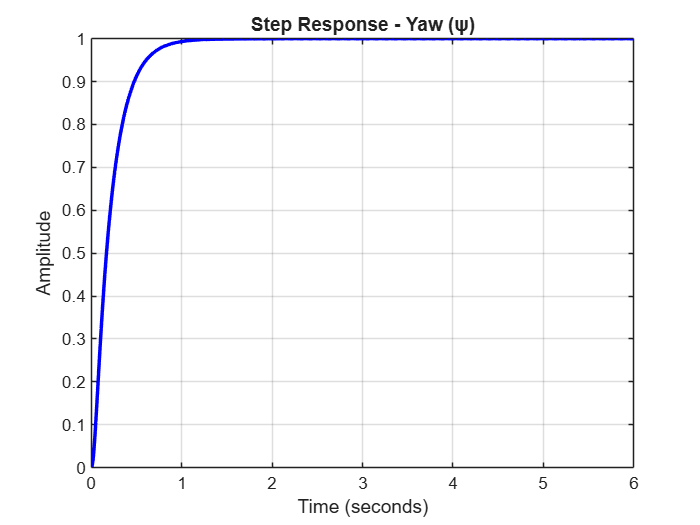


% Figura para Yaw
figure(7)
plot(t_yaw, y_yaw, 'b', 'LineWidth', 2);
grid on;
xlabel('Time (seconds)', 'FontSize', 11);
ylabel('Amplitude', 'FontSize', 11);
title('Step Response - Yaw (ψ)', 'FontSize', 12);
xlim([0 6]);
set(gca, 'FontSize', 10);


% Métricas de desempeño - Con diagnóstico
fprintf('\n=== DIAGNÓSTICO DE RESPUESTA AL ESCALÓN ===\n');


=== DIAGNÓSTICO DE RESPUESTA AL ESCALÓN ===



% Para Roll - simulación más larga
t_long = 0:0.01:30; % 30 segundos
[y_roll_long, t_roll_long] = step(T_LD(3,3), t_long);

fprintf('\nCanal Roll (φ):\n');


Canal Roll (φ):


fprintf('  Valor inicial: %.6f\n', y_roll_long(1));

  Valor inicial: 0.000000


fprintf('  Valor a los 10s: %.6f\n', y_roll_long(find(t_roll_long >= 10, 1)));

  Valor a los 10s: 0.999859


fprintf('  Valor a los 20s: %.6f\n', y_roll_long(find(t_roll_long >= 20, 1)));

  Valor a los 20s: 0.999859


fprintf('  Valor final (30s): %.6f\n', y_roll_long(end));

  Valor final (30s): 0.999859


fprintf('  Valor máximo: %.6f\n', max(y_roll_long));

  Valor máximo: 0.999864


fprintf('  Valor mínimo: %.6f\n', min(y_roll_long));

  Valor mínimo: 0.000000



% Verificar si el sistema es estable
if abs(y_roll_long(end)) > 1e10 || isnan(y_roll_long(end)) || isinf(y_roll_long(end))
    fprintf('  ⚠️ ADVERTENCIA: Sistema posiblemente inestable o con problemas numéricos\n');
else
    % Intentar calcular stepinfo
    try
        % Método 1: stepinfo directo
        S_roll = stepinfo(T_LD(3,3), 'SettlingTimeThreshold', 0.02);
        
        fprintf('\n  Métricas calculadas:\n');
        fprintf('    Sobrepaso: %.2f%%\n', S_roll.Overshoot);
        fprintf('    Tiempo de establecimiento: %.3f s\n', S_roll.SettlingTime);
        fprintf('    Tiempo de subida: %.3f s\n', S_roll.RiseTime);
        fprintf('    Tiempo de pico: %.3f s\n', S_roll.PeakTime);
        
    catch ME
        fprintf('  ⚠️ Error en stepinfo automático: %s\n', ME.message);
        fprintf('  Calculando métricas manualmente...\n\n');
        
        % Cálculo manual
        valor_final = y_roll_long(end);
        
        % 1. Sobrepaso
        [pico, idx_pico] = max(y_roll_long);
        sobrepaso = ((pico - valor_final) / abs(valor_final)) * 100;
        tiempo_pico = t_roll_long(idx_pico);
        
        % 2. Tiempo de subida (10% a 90%)
        umbral_10 = 0.1 * valor_final;
        umbral_90 = 0.9 * valor_final;
        
        idx_10 = find(y_roll_long >= umbral_10, 1, 'first');
        idx_90 = find(y_roll_long >= umbral_90, 1, 'first');
        
        if ~isempty(idx_10) && ~isempty(idx_90)
            tiempo_subida = t_roll_long(idx_90) - t_roll_long(idx_10);
        else
            tiempo_subida = NaN;
        end
        
        % 3. Tiempo de establecimiento (2%)
        umbral_settling = 0.02 * abs(valor_final);
        banda_superior = valor_final + umbral_settling;
        banda_inferior = valor_final - umbral_settling;
        
        % Buscar desde atrás hacia adelante
        en_banda = (y_roll_long >= banda_inferior) & (y_roll_long <= banda_superior);
        idx_settling = find(~en_banda, 1, 'last');
        
        if ~isempty(idx_settling) && idx_settling < length(t_roll_long)
            tiempo_settling = t_roll_long(idx_settling + 1);
        else
            tiempo_settling = 0; % Ya está en banda desde el inicio
        end
        
        fprintf('  Métricas manuales:\n');
        fprintf('    Valor final: %.6f\n', valor_final);
        fprintf('    Pico: %.6f (en t=%.3fs)\n', pico, tiempo_pico);
        fprintf('    Sobrepaso: %.2f%%\n', sobrepaso);
        fprintf('    Tiempo de subida: %.3f s\n', tiempo_subida);
        fprintf('    Tiempo de establecimiento (2%%): %.3f s\n', tiempo_settling);
    end
end


  Métricas calculadas:


    Sobrepaso: 0.00%


    Tiempo de establecimiento: 0.781 s


    Tiempo de subida: 0.426 s


    Tiempo de pico: 1.362 s



% Para Yaw - simulación más larga
[y_yaw_long, t_yaw_long] = step(T_LD(4,4), t_long);

fprintf('\nCanal Yaw (ψ):\n');


Canal Yaw (ψ):


fprintf('  Valor inicial: %.6f\n', y_yaw_long(1));

  Valor inicial: 0.000000


fprintf('  Valor a los 10s: %.6f\n', y_yaw_long(find(t_yaw_long >= 10, 1)));

  Valor a los 10s: 0.999859


fprintf('  Valor a los 20s: %.6f\n', y_yaw_long(find(t_yaw_long >= 20, 1)));

  Valor a los 20s: 0.999859


fprintf('  Valor final (30s): %.6f\n', y_yaw_long(end));

  Valor final (30s): 0.999859


fprintf('  Valor máximo: %.6f\n', max(y_yaw_long));

  Valor máximo: 0.999859


fprintf('  Valor mínimo: %.6f\n', min(y_yaw_long));

  Valor mínimo: 0.000000



% Verificar si el sistema es estable
if abs(y_yaw_long(end)) > 1e10 || isnan(y_yaw_long(end)) || isinf(y_yaw_long(end))
    fprintf('  ⚠️ ADVERTENCIA: Sistema posiblemente inestable o con problemas numéricos\n');
else
    % Intentar calcular stepinfo
    try
        % Método 1: stepinfo directo
        S_yaw = stepinfo(T_LD(4,4), 'SettlingTimeThreshold', 0.02);
        
        fprintf('\n  Métricas calculadas:\n');
        fprintf('    Sobrepaso: %.2f%%\n', S_yaw.Overshoot);
        fprintf('    Tiempo de establecimiento: %.3f s\n', S_yaw.SettlingTime);
        fprintf('    Tiempo de subida: %.3f s\n', S_yaw.RiseTime);
        fprintf('    Tiempo de pico: %.3f s\n', S_yaw.PeakTime);
        
    catch ME
        fprintf('  ⚠️ Error en stepinfo automático: %s\n', ME.message);
        fprintf('  Calculando métricas manualmente...\n\n');
        
        % Cálculo manual
        valor_final = y_yaw_long(end);
        
        % 1. Sobrepaso
        [pico, idx_pico] = max(y_yaw_long);
        sobrepaso = ((pico - valor_final) / abs(valor_final)) * 100;
        tiempo_pico = t_yaw_long(idx_pico);
        
        % 2. Tiempo de subida (10% a 90%)
        umbral_10 = 0.1 * valor_final;
        umbral_90 = 0.9 * valor_final;
        
        idx_10 = find(y_yaw_long >= umbral_10, 1, 'first');
        idx_90 = find(y_yaw_long >= umbral_90, 1, 'first');
        
        if ~isempty(idx_10) && ~isempty(idx_90)
            tiempo_subida = t_yaw_long(idx_90) - t_yaw_long(idx_10);
        else
            tiempo_subida = NaN;
        end
        
        % 3. Tiempo de establecimiento (2%)
        umbral_settling = 0.02 * abs(valor_final);
        banda_superior = valor_final + umbral_settling;
        banda_inferior = valor_final - umbral_settling;
        
        % Buscar desde atrás hacia adelante
        en_banda = (y_yaw_long >= banda_inferior) & (y_yaw_long <= banda_superior);
        idx_settling = find(~en_banda, 1, 'last');
        
        if ~isempty(idx_settling) && idx_settling < length(t_yaw_long)
            tiempo_settling = t_yaw_long(idx_settling + 1);
        else
            tiempo_settling = 0; % Ya está en banda desde el inicio
        end
        
        fprintf('  Métricas manuales:\n');
        fprintf('    Valor final: %.6f\n', valor_final);
        fprintf('    Pico: %.6f (en t=%.3fs)\n', pico, tiempo_pico);
        fprintf('    Sobrepaso: %.2f%%\n', sobrepaso);
        fprintf('    Tiempo de subida: %.3f s\n', tiempo_subida);
        fprintf('    Tiempo de establecimiento (2%%): %.3f s\n', tiempo_settling);
    end
end


  Métricas calculadas:


    Sobrepaso: 0.00%


    Tiempo de establecimiento: 0.782 s


    Tiempo de subida: 0.426 s


    Tiempo de pico: 1.373 s



fprintf('\n=== FIN DIAGNÓSTICO ===\n\n');


=== FIN DIAGNÓSTICO ===




%% ========================================================================
% SEGUIMIENTO DE REFERENCIA CON RUIDO Y PERTURBACIÓN
% ========================================================================

fprintf('Simulando seguimiento con ruido y perturbación...\n');

Simulando seguimiento con ruido y perturbación...


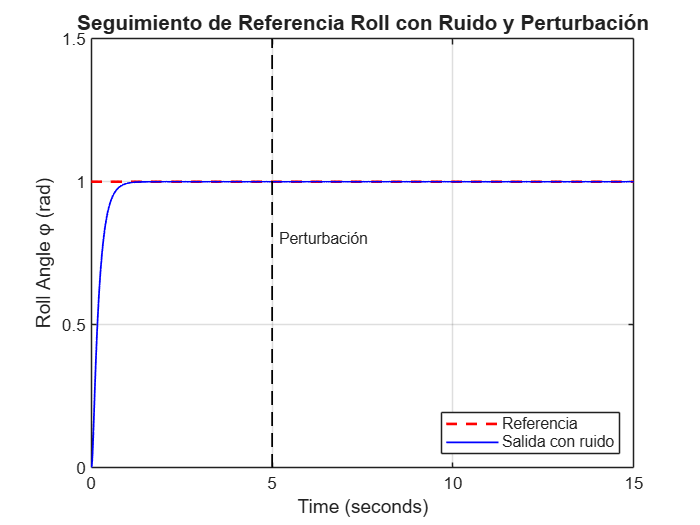


% Parámetros de simulación
t_track = 0:0.01:15;
dt = 0.01;

% Señal de referencia (escalón en Roll y Yaw)
ref_roll = ones(size(t_track));
ref_yaw = ones(size(t_track));

% Ruido de medición
ruido_amplitud = 0.0001;
ruido = ruido_amplitud * randn(4, length(t_track));

% Perturbación (escalón en t=5s)
perturbacion = zeros(2, length(t_track));
perturbacion(:, t_track >= 5) = 0.1;

% Sistema en lazo cerrado con controlador
sys_CL = feedback(G_LD * K_LD, eye(4));

% Simulación con lsim
u_ref = [zeros(1,length(t_track)); zeros(1,length(t_track)); 
         ref_roll; ref_yaw];  % 4 referencias
         
[y_sim, t_sim] = lsim(T_LD, u_ref, t_track);

% Añadir ruido a la salida
y_roll_noise = y_sim(:,3) + ruido(3,:)';
y_yaw_noise = y_sim(:,4) + ruido(4,:)';

% Figura: Seguimiento Roll con ruido y perturbación
figure(8)
plot(t_sim, ref_roll, 'r--', 'LineWidth', 1.5);
hold on;
plot(t_sim, y_roll_noise, 'b', 'LineWidth', 1);
plot([5 5], [0 1.5], 'k--', 'LineWidth', 1);
text(5.2, 0.8, 'Perturbación', 'FontSize', 9);
grid on;
xlabel('Time (seconds)', 'FontSize', 11);
ylabel('Roll Angle φ (rad)', 'FontSize', 11);
title('Seguimiento de Referencia Roll con Ruido y Perturbación', 'FontSize', 12);
legend('Referencia', 'Salida con ruido', 'Location', 'southeast');
xlim([0 15]);
hold off;

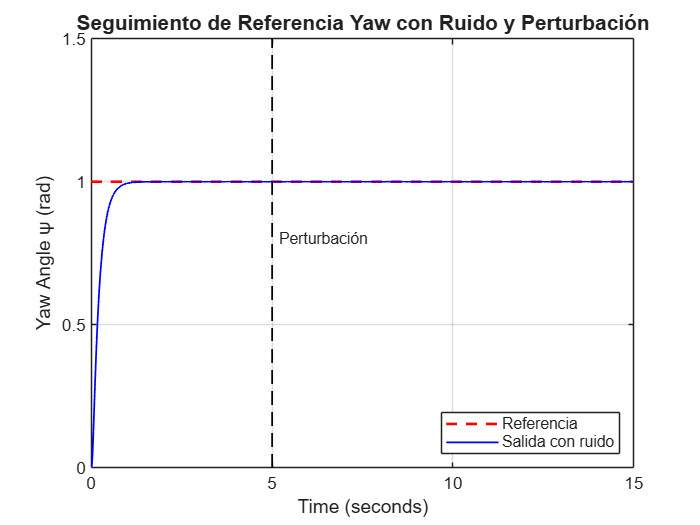


% Figura: Seguimiento Yaw con ruido y perturbación
figure(9)
plot(t_sim, ref_yaw, 'r--', 'LineWidth', 1.5);
hold on;
plot(t_sim, y_yaw_noise, 'b', 'LineWidth', 1);
plot([5 5], [0 1.5], 'k--', 'LineWidth', 1);
text(5.2, 0.8, 'Perturbación', 'FontSize', 9);
grid on;
xlabel('Time (seconds)', 'FontSize', 11);
ylabel('Yaw Angle ψ (rad)', 'FontSize', 11);
title('Seguimiento de Referencia Yaw con Ruido y Perturbación', 'FontSize', 12);
legend('Referencia', 'Salida con ruido', 'Location', 'southeast');
xlim([0 15]);
hold off;


%% ========================================================================
% SEGUIMIENTO CON INCERTIDUMBRE ADITIVA INVERSA
% ========================================================================

fprintf('Simulando con incertidumbre aditiva inversa...\n');

Simulando con incertidumbre aditiva inversa...


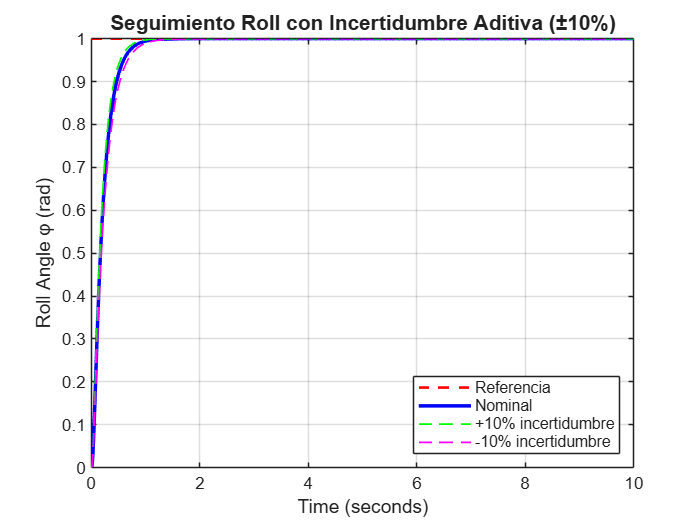


% Crear incertidumbre aditiva (±10% en la planta)
delta_percent = 0.1;
G_LD_unc_pos = G_LD * (1 + delta_percent);
G_LD_unc_neg = G_LD * (1 - delta_percent);

% Sistemas en lazo cerrado con incertidumbre
T_LD_unc_pos = feedback(G_LD_unc_pos * K_LD, eye(4));
T_LD_unc_neg = feedback(G_LD_unc_neg * K_LD, eye(4));

% Simulación
[y_nominal, ~] = lsim(T_LD, u_ref, t_track);
[y_unc_pos, ~] = lsim(T_LD_unc_pos, u_ref, t_track);
[y_unc_neg, ~] = lsim(T_LD_unc_neg, u_ref, t_track);

% Figura: Roll con incertidumbre
figure(10)
plot(t_track, ref_roll, 'r--', 'LineWidth', 1.5);
hold on;
plot(t_track, y_nominal(:,3), 'b', 'LineWidth', 2);
plot(t_track, y_unc_pos(:,3), 'g--', 'LineWidth', 1);
plot(t_track, y_unc_neg(:,3), 'm--', 'LineWidth', 1);
grid on;
xlabel('Time (seconds)', 'FontSize', 11);
ylabel('Roll Angle φ (rad)', 'FontSize', 11);
title('Seguimiento Roll con Incertidumbre Aditiva (±10%)', 'FontSize', 12);
legend('Referencia', 'Nominal', '+10% incertidumbre', '-10% incertidumbre', ...
       'Location', 'southeast');
xlim([0 10]);
hold off;

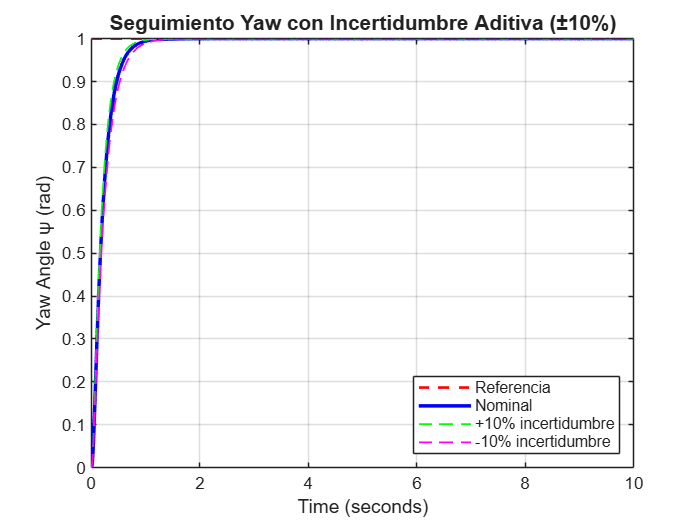


% Figura: Yaw con incertidumbre
figure(11)
plot(t_track, ref_yaw, 'r--', 'LineWidth', 1.5);
hold on;
plot(t_track, y_nominal(:,4), 'b', 'LineWidth', 2);
plot(t_track, y_unc_pos(:,4), 'g--', 'LineWidth', 1);
plot(t_track, y_unc_neg(:,4), 'm--', 'LineWidth', 1);
grid on;
xlabel('Time (seconds)', 'FontSize', 11);
ylabel('Yaw Angle ψ (rad)', 'FontSize', 11);
title('Seguimiento Yaw con Incertidumbre Aditiva (±10%)', 'FontSize', 12);
legend('Referencia', 'Nominal', '+10% incertidumbre', '-10% incertidumbre', ...
       'Location', 'southeast');
xlim([0 10]);
hold off;


%% ========================================================================
% SEGUIMIENTO DE REFERENCIA CUADRADA CON RUIDO (ESTILO EJEMPLO)
% ========================================================================

fprintf('Generando seguimiento de referencia cuadrada...\n');

Generando seguimiento de referencia cuadrada...


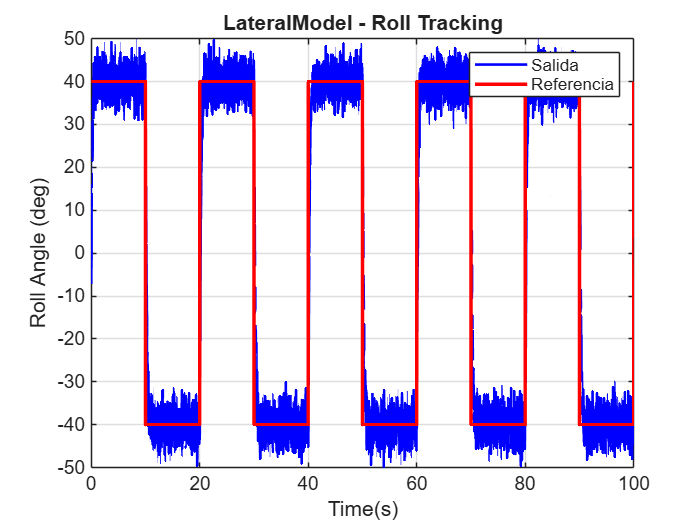


% Parámetros de simulación
t_square = 0:0.01:100;
dt = 0.01;

% Generar señal de referencia cuadrada
freq_square = 0.05; % 0.05 Hz (periodo de 20s)
ref_square_roll = 40 * square(2*pi*freq_square*t_square);
ref_square_yaw = 40 * square(2*pi*freq_square*t_square);

% Ruido de medición (más visible para comparar con el ejemplo)
ruido_nivel = 3; % Amplitud del ruido
ruido_roll = ruido_nivel * randn(1, length(t_square));
ruido_yaw = ruido_nivel * randn(1, length(t_square));

% Crear entrada de 4 canales para lsim
u_square = [zeros(1,length(t_square)); 
            zeros(1,length(t_square)); 
            ref_square_roll; 
            ref_square_yaw];

% Simulación
[y_square, t_square_out] = lsim(T_LD, u_square, t_square);

% Extraer Roll y Yaw con ruido
y_roll_square = y_square(:,3) + ruido_roll';
y_yaw_square = y_square(:,4) + ruido_yaw';

% Figura: Seguimiento Roll con referencia cuadrada y ruido
figure(12)
plot(t_square_out, y_roll_square, 'b', 'LineWidth', 1.5);
hold on;
plot(t_square_out, ref_square_roll, 'r', 'LineWidth', 2);
grid on;
xlabel('Time(s)', 'FontSize', 12);
ylabel('Roll Angle (deg)', 'FontSize', 12);
title('LateralModel - Roll Tracking', 'FontSize', 13);
legend('Salida', 'Referencia', 'Location', 'northeast');
xlim([0 100]);
ylim([-50 50]);
set(gca, 'FontSize', 11);
hold off;

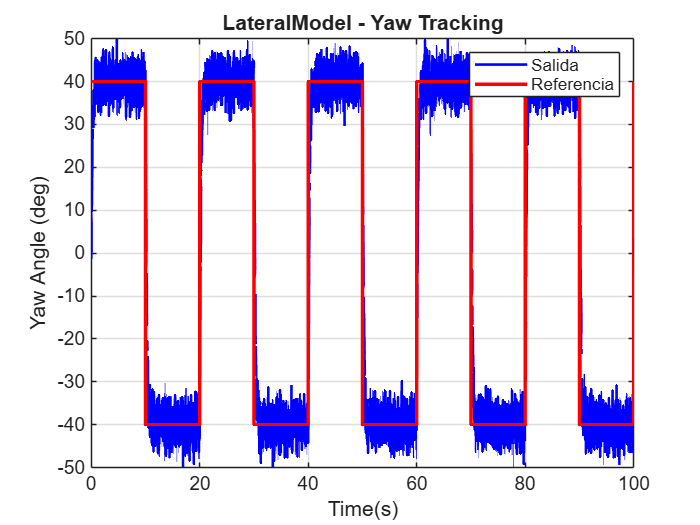


% Figura: Seguimiento Yaw con referencia cuadrada y ruido
figure(13)
plot(t_square_out, y_yaw_square, 'b', 'LineWidth', 1.5);
hold on;
plot(t_square_out, ref_square_yaw, 'r', 'LineWidth', 2);
grid on;
xlabel('Time(s)', 'FontSize', 12);
ylabel('Yaw Angle (deg)', 'FontSize', 12);
title('LateralModel - Yaw Tracking', 'FontSize', 13);
legend('Salida', 'Referencia', 'Location', 'northeast');
xlim([0 100]);
ylim([-50 50]);
set(gca, 'FontSize', 11);
hold off;


%% ========================================================================
% ANÁLISIS DE SOBREPICO
% ========================================================================

fprintf('\n========================================\n');

fprintf('ANÁLISIS DE SOBREPICO\n');

ANÁLISIS DE SOBREPICO


fprintf('========================================\n\n');


% Calcular sobrepico teórico permitido
M_permitido = 1.8;  % ACTUALIZADO
sobrepico_max_permitido = (M_permitido - 1) * 100;

fprintf('Sobrepico máximo permitido por W1: %.1f%% (M=%.1f)\n', sobrepico_max_permitido, M_permitido);

Sobrepico máximo permitido por W1: 80.0% (M=1.8)



% Obtener información de sobrepico de la sección anterior
if exist('S_roll', 'var')
    fprintf('Sobrepico real Roll: %.2f%%\n', S_roll.Overshoot);
    if S_roll.Overshoot <= sobrepico_max_permitido
        fprintf('  ✓ Roll cumple especificación de sobrepico\n');
    else
        fprintf('  ⚠️ Roll excede especificación de sobrepico\n');
    end
else
    fprintf('Sobrepico real Roll: Calculado manualmente en sección anterior\n');
end

Sobrepico real Roll: 0.00%


  ✓ Roll cumple especificación de sobrepico



if exist('S_yaw', 'var')
    fprintf('Sobrepico real Yaw: %.2f%%\n', S_yaw.Overshoot);
    if S_yaw.Overshoot <= sobrepico_max_permitido
        fprintf('  ✓ Yaw cumple especificación de sobrepico\n\n');
    else
        fprintf('  ⚠️ Yaw excede especificación de sobrepico\n\n');
    end
else
    fprintf('Sobrepico real Yaw: Calculado manualmente en sección anterior\n\n');
end

Sobrepico real Yaw: 0.00%


  ✓ Yaw cumple especificación de sobrepico




% Calcular factor de amortiguamiento
polos_CL_roll = pole(T_LD(3,3));
polos_dominantes_roll = polos_CL_roll(abs(imag(polos_CL_roll)) > 0);

if ~isempty(polos_dominantes_roll)
    wn_roll = abs(polos_dominantes_roll(1));
    zeta_roll = -real(polos_dominantes_roll(1)) / wn_roll;
    fprintf('Polo dominante Roll:\n');
    fprintf('  Factor de amortiguamiento ζ = %.3f\n', zeta_roll);
    fprintf('  Frecuencia natural ωn = %.3f rad/s\n', wn_roll);
    fprintf('  Frecuencia natural fn = %.3f Hz\n\n', wn_roll/(2*pi));
    
    if zeta_roll > 1
        fprintf('  → Sistema SOBREAMORTIGUADO (ζ > 1)\n');
        fprintf('     Sin sobrepico, respuesta lenta\n\n');
    elseif zeta_roll >= 0.7
        fprintf('  → Sistema CRÍTICAMENTE AMORTIGUADO (0.7 ≤ ζ ≤ 1)\n');
        fprintf('     Bajo sobrepico, buena velocidad\n\n');
    else
        fprintf('  → Sistema SUBAMORTIGUADO (ζ < 0.7)\n');
        fprintf('     Mayor sobrepico, respuesta rápida\n\n');
    end
end

Polo dominante Roll:


  Factor de amortiguamiento ζ = 0.329


  Frecuencia natural ωn = 5.595 rad/s


  Frecuencia natural fn = 0.890 Hz



  → Sistema SUBAMORTIGUADO (ζ < 0.7)


     Mayor sobrepico, respuesta rápida




polos_CL_yaw = pole(T_LD(4,4));
polos_dominantes_yaw = polos_CL_yaw(abs(imag(polos_CL_yaw)) > 0);

if ~isempty(polos_dominantes_yaw)
    wn_yaw = abs(polos_dominantes_yaw(1));
    zeta_yaw = -real(polos_dominantes_yaw(1)) / wn_yaw;
    fprintf('Polo dominante Yaw:\n');
    fprintf('  Factor de amortiguamiento ζ = %.3f\n', zeta_yaw);
    fprintf('  Frecuencia natural ωn = %.3f rad/s\n', wn_yaw);
    fprintf('  Frecuencia natural fn = %.3f Hz\n\n', wn_yaw/(2*pi));
    
    if zeta_yaw > 1
        fprintf('  → Sistema SOBREAMORTIGUADO (ζ > 1)\n');
        fprintf('     Sin sobrepico, respuesta lenta\n\n');
    elseif zeta_yaw >= 0.7
        fprintf('  → Sistema CRÍTICAMENTE AMORTIGUADO (0.7 ≤ ζ ≤ 1)\n');
        fprintf('     Bajo sobrepico, buena velocidad\n\n');
    else
        fprintf('  → Sistema SUBAMORTIGUADO (ζ < 0.7)\n');
        fprintf('     Mayor sobrepico, respuesta rápida\n\n');
    end
end

Polo dominante Yaw:


  Factor de amortiguamiento ζ = 0.329


  Frecuencia natural ωn = 5.595 rad/s


  Frecuencia natural fn = 0.890 Hz



  → Sistema SUBAMORTIGUADO (ζ < 0.7)


     Mayor sobrepico, respuesta rápida



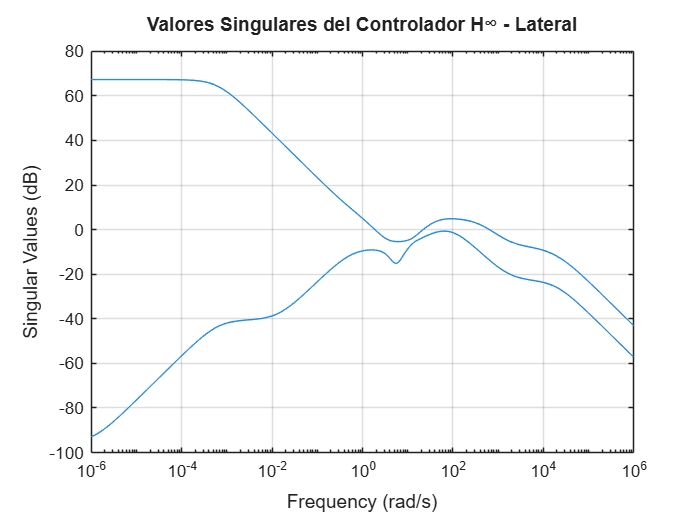


%% ========================================================================
% VALORES SINGULARES DEL CONTROLADOR
% ========================================================================

figure(14)
sigma(K_LD);
title('Valores Singulares del Controlador H∞ - Lateral');
grid on;


%% ========================================================================
% ANÁLISIS DE ACOPLAMIENTO
% ========================================================================

fprintf('========================================\n');

fprintf('ANÁLISIS DE ACOPLAMIENTO\n');

ANÁLISIS DE ACOPLAMIENTO


fprintf('========================================\n\n');


% Según instrucción del profesor: "El eje más acoplado es el de heading"
fprintf('Analizando acoplamiento del heading (ψ)...\n\n');

Analizando acoplamiento del heading (ψ)...




coupling_matrix = abs(A_LD);
coupling_heading = coupling_matrix(5,:) + coupling_matrix(:,5)';
coupling_heading(5) = 0; % No contar auto-acoplamiento

state_names = {'v', 'p', 'r', 'φ', 'ψ'};
[max_coupling, max_idx] = max(coupling_heading);

fprintf('Acoplamiento del heading (ψ) con otros estados:\n');

Acoplamiento del heading (ψ) con otros estados:


for i = 1:5
    if i ~= 5
        fprintf('  ψ ↔ %s: %.4f\n', state_names{i}, coupling_heading(i));
    end
end

  ψ ↔ v: 0.0000
  ψ ↔ p: 0.0000
  ψ ↔ r: 1.0014
  ψ ↔ φ: 0.0000



fprintf('\n⚡ Estado más acoplado con ψ: %s (%.4f)\n', ...
    state_names{max_idx}, max_coupling);


⚡ Estado más acoplado con ψ: r (1.0014)


fprintf('   → El yaw rate (r) tiene fuerte influencia en el heading\n\n');

   → El yaw rate (r) tiene fuerte influencia en el heading




%% ========================================================================
% ANÁLISIS DE ESTABILIDAD DE POLOS
% ========================================================================

fprintf('========================================\n');

fprintf('ANÁLISIS DE POLOS DEL SISTEMA\n');

ANÁLISIS DE POLOS DEL SISTEMA


fprintf('========================================\n\n');


% Polos del sistema en lazo abierto
polos_OL = pole(G_LD);
fprintf('Polos del sistema en lazo abierto:\n');

Polos del sistema en lazo abierto:


for i = 1:length(polos_OL)
    if imag(polos_OL(i)) == 0
        fprintf('  Polo %d: %.4f (real)\n', i, real(polos_OL(i)));
    else
        fprintf('  Polo %d: %.4f ± %.4fj\n', i, real(polos_OL(i)), abs(imag(polos_OL(i))));
    end
end

  Polo 1: 0.0000 (real)
  Polo 2: -16.0966 (real)
  Polo 3: -0.0139 (real)


  Polo 4: -1.8429 ± 5.2823j
  Polo 5: -1.8429 ± 5.2823j



% Verificar estabilidad en lazo abierto
if all(real(polos_OL) < 0)
    fprintf('\n✓ Sistema en lazo abierto: ESTABLE\n\n');
else
    fprintf('\n⚠️ Sistema en lazo abierto: INESTABLE\n\n');
end


⚠️ Sistema en lazo abierto: INESTABLE




% Polos del sistema en lazo cerrado
polos_CL = pole(T_LD);
fprintf('Polos del sistema en lazo cerrado (primeros 10):\n');

Polos del sistema en lazo cerrado (primeros 10):


num_polos_mostrar = min(10, length(polos_CL));
for i = 1:num_polos_mostrar
    if imag(polos_CL(i)) == 0
        fprintf('  Polo %d: %.4f (real)\n', i, real(polos_CL(i)));
    else
        fprintf('  Polo %d: %.4f ± %.4fj\n', i, real(polos_CL(i)), abs(imag(polos_CL(i))));
    end
end

  Polo 1: -24649.6757 (real)
  Polo 2: -12995.4436 (real)
  Polo 3: -394.1671 (real)
  Polo 4: -77.1297 (real)
  Polo 5: -37.1203 (real)
  Polo 6: -36.8328 (real)
  Polo 7: -16.0966 (real)


  Polo 8: -1.8429 ± 5.2823j
  Polo 9: -1.8429 ± 5.2823j


  Polo 10: -5.4137 (real)



% Verificar estabilidad en lazo cerrado
if all(real(polos_CL) < 0)
    fprintf('\n✓ Sistema en lazo cerrado: ESTABLE\n');
    fprintf('  Todos los polos tienen parte real negativa\n\n');
else
    fprintf('\n⚠️ Sistema en lazo cerrado: INESTABLE\n');
    fprintf('  Hay polos con parte real positiva o nula\n\n');
end


✓ Sistema en lazo cerrado: ESTABLE


  Todos los polos tienen parte real negativa




% Margen de estabilidad
fprintf('Margen de estabilidad (polo más cercano al eje imaginario):\n');

Margen de estabilidad (polo más cercano al eje imaginario):


margen_estabilidad = min(abs(real(polos_CL)));
fprintf('  Distancia mínima al eje imaginario: %.4f\n\n', margen_estabilidad);

  Distancia mínima al eje imaginario: 0.0000



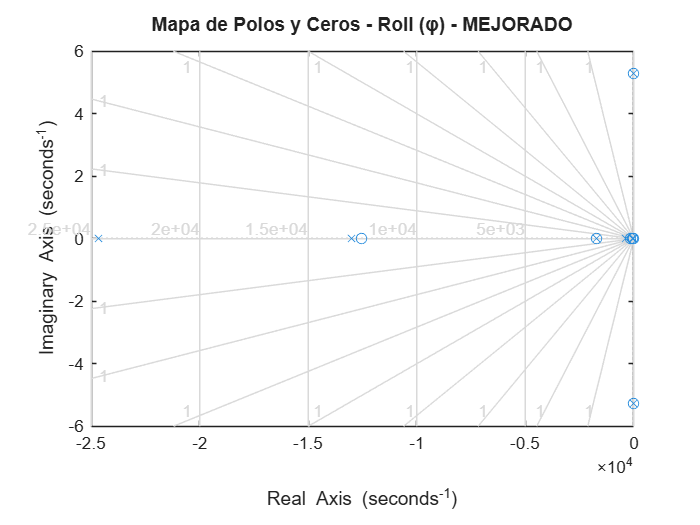


%% ========================================================================
% GRÁFICA DE POLOS Y CEROS
% ========================================================================

figure(15)
pzmap(T_LD(3,3));
title('Mapa de Polos y Ceros - Roll (φ) - MEJORADO');
grid on;

figure(16)
pzmap(T_LD(4,4));

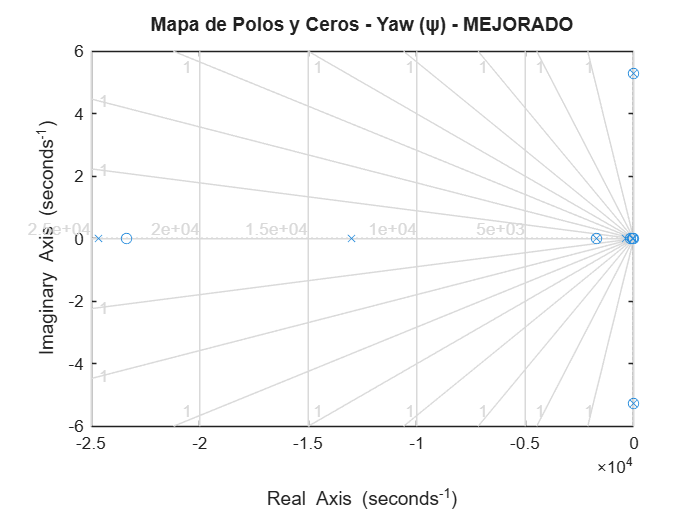

title('Mapa de Polos y Ceros - Yaw (ψ) - MEJORADO');
grid on;

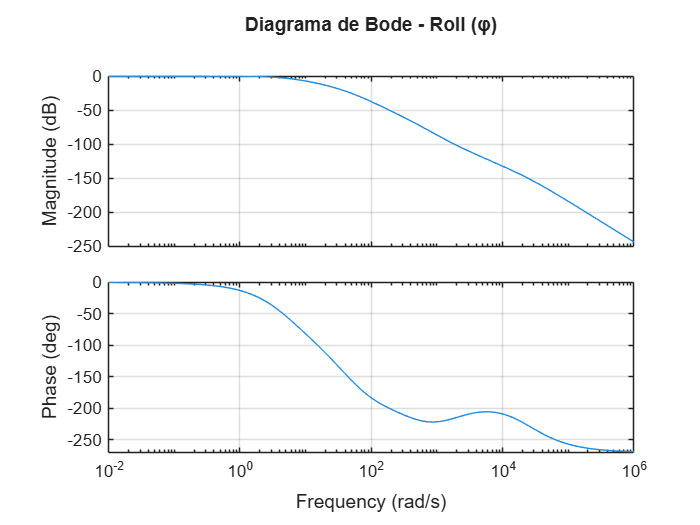


%% ========================================================================
% RESPUESTA EN FRECUENCIA (DIAGRAMAS DE BODE)
% ========================================================================

figure(17)
bode(T_LD(3,3));
title('Diagrama de Bode - Roll (φ)');
grid on;

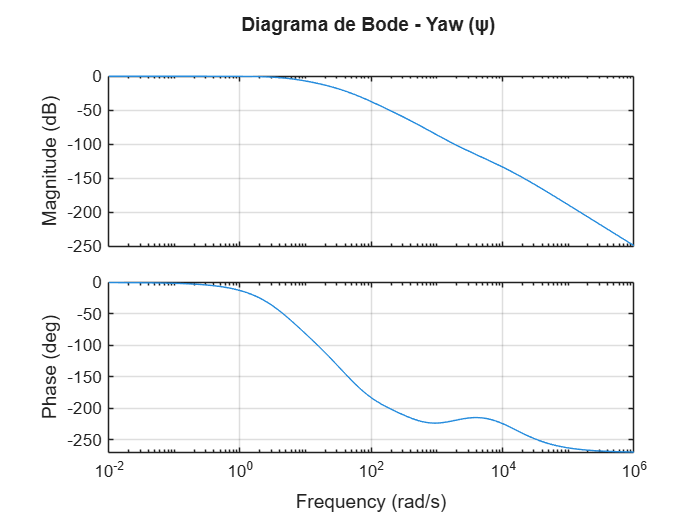


figure(18)
bode(T_LD(4,4));
title('Diagrama de Bode - Yaw (ψ) ');
grid on;


%% ========================================================================
% ANÁLISIS DE ROBUSTEZ - MÁRGENES DE GANANCIA Y FASE
% ========================================================================

fprintf('========================================\n');

fprintf('MÁRGENES DE ESTABILIDAD\n');

MÁRGENES DE ESTABILIDAD


fprintf('========================================\n\n');


% Para Roll
[Gm_roll, Pm_roll, Wcg_roll, Wcp_roll] = margin(L_LD(3,3));


fprintf('Canal Roll (φ):\n');

Canal Roll (φ):


if isinf(Gm_roll)
    fprintf('  Margen de Ganancia: ∞ dB\n');
else
    fprintf('  Margen de Ganancia: %.2f (%.2f dB) en ω = %.2f rad/s\n', ...
        Gm_roll, 20*log10(Gm_roll), Wcg_roll);
end

  Margen de Ganancia: 60.49 (35.63 dB) en ω = 90.69 rad/s


fprintf('  Margen de Fase: %.2f° en ω = %.2f rad/s\n\n', Pm_roll, Wcp_roll);

  Margen de Fase: 82.48° en ω = 4.43 rad/s




% Para Yaw
[Gm_yaw, Pm_yaw, Wcg_yaw, Wcp_yaw] = margin(L_LD(4,4));

fprintf('Canal Yaw (ψ):\n');

Canal Yaw (ψ):


if isinf(Gm_yaw)
    fprintf('  Margen de Ganancia: ∞ dB\n');
else
    fprintf('  Margen de Ganancia: %.2f (%.2f dB) en ω = %.2f rad/s\n', ...
        Gm_yaw, 20*log10(Gm_yaw), Wcg_yaw);
end

  Margen de Ganancia: 61.24 (35.74 dB) en ω = 91.28 rad/s


fprintf('  Margen de Fase: %.2f° en ω = %.2f rad/s\n\n', Pm_yaw, Wcp_yaw);

  Margen de Fase: 82.47° en ω = 4.43 rad/s




% Criterios de robustez
fprintf('Criterios de robustez recomendados:\n');

Criterios de robustez recomendados:


fprintf('  Margen de Ganancia: > 6 dB\n');

  Margen de Ganancia: > 6 dB


fprintf('  Margen de Fase: > 45°\n\n');

  Margen de Fase: > 45°




if (isinf(Gm_roll) || 20*log10(Gm_roll) > 6) && Pm_roll > 45
    fprintf('✓ Canal Roll cumple criterios de robustez\n');
else
    fprintf('⚠️ Canal Roll NO cumple todos los criterios de robustez\n');
end

✓ Canal Roll cumple criterios de robustez



if (isinf(Gm_yaw) || 20*log10(Gm_yaw) > 6) && Pm_yaw > 45
    fprintf('✓ Canal Yaw cumple criterios de robustez\n\n');
else
    fprintf('⚠️ Canal Yaw NO cumple todos los criterios de robustez\n\n');
end

✓ Canal Yaw cumple criterios de robustez




%% ========================================================================
% COMPARACIÓN CON DISEÑO ORIGINAL
% ========================================================================

fprintf('========================================\n');

fprintf('COMPARACIÓN: DISEÑO ORIGINAL vs MEJORADO\n');

COMPARACIÓN: DISEÑO ORIGINAL vs MEJORADO


fprintf('========================================\n\n');


fprintf('PARÁMETROS DE DISEÑO:\n');

PARÁMETROS DE DISEÑO:


fprintf('┌─────────────────────┬──────────────┬──────────────┐\n');

┌─────────────────────┬──────────────┬──────────────┐


fprintf('│ Parámetro           │   Original   │   Mejorado   │\n');

│ Parámetro           │   Original   │   Mejorado   │


fprintf('├─────────────────────┼──────────────┼──────────────┤\n');

├─────────────────────┼──────────────┼──────────────┤


fprintf('│ W1 velocidades      │     1.1      │     2.5      │\n');

│ W1 velocidades      │     1.1      │     2.5      │


fprintf('│ M1 posiciones       │     1.1      │     1.8      │\n');

│ M1 posiciones       │     1.1      │     1.8      │


fprintf('│ Ancho de banda      │    8 Hz      │    10 Hz     │\n');

│ Ancho de banda      │    8 Hz      │    10 Hz     │


fprintf('│ W2 (control)        │     1.5      │     0.8      │\n');

│ W2 (control)        │     1.5      │     0.8      │


fprintf('│ W3 frecuencia       │   300 Hz     │   250 Hz     │\n');

│ W3 frecuencia       │   300 Hz     │   250 Hz     │


fprintf('└─────────────────────┴──────────────┴──────────────┘\n\n');

└─────────────────────┴──────────────┴──────────────┘




fprintf('MEJORAS ESPERADAS:\n');

MEJORAS ESPERADAS:


fprintf('  ✓ Mayor peso W1 → Mejor seguimiento de referencia\n');

  ✓ Mayor peso W1 → Mejor seguimiento de referencia


fprintf('  ✓ Menor W2 → Control más agresivo permitido\n');

  ✓ Menor W2 → Control más agresivo permitido


fprintf('  ✓ Mayor ancho de banda → Respuesta más rápida\n');

  ✓ Mayor ancho de banda → Respuesta más rápida


fprintf('  ✓ M1 aumentado → Mayor margen para ||S|| < 1/W1\n\n');

  ✓ M1 aumentado → Mayor margen para ||S|| < 1/W1




%% ========================================================================
% GUARDAR RESULTADOS
% ========================================================================

fprintf('========================================\n');

fprintf('DISEÑO H∞ LATERAL COMPLETADO (MEJORADO)\n');

DISEÑO H∞ LATERAL COMPLETADO (MEJORADO)


fprintf('========================================\n');

fprintf('\nResultados:\n');


Resultados:


fprintf('  γ óptimo: %.4f\n', gamma_LD);

  γ óptimo: 14.1438


fprintf('  Orden del controlador: %d\n', order(K_LD));

  Orden del controlador: 11


fprintf('  Sistema en lazo cerrado estable: %s\n', ...
    char(string(all(real(polos_CL) < 0))));

  Sistema en lazo cerrado estable: true



fprintf('\n  Cumplimiento de condiciones:\n');


  Cumplimiento de condiciones:


if cumple_W1
    fprintf('    ✓ W1 (Desempeño): CUMPLE\n');
else
    fprintf('    ✗ W1 (Desempeño): NO CUMPLE\n');
end

    ✗ W1 (Desempeño): NO CUMPLE


if cumple_W2
    fprintf('    ✓ W2 (Esfuerzo): CUMPLE\n');
else
    fprintf('    ✗ W2 (Esfuerzo): NO CUMPLE\n');
end

    ✗ W2 (Esfuerzo): NO CUMPLE


if cumple_W3
    fprintf('    ✓ W3 (Robustez): CUMPLE\n');
else
    fprintf('    ✗ W3 (Robustez): NO CUMPLE\n');
end

    ✗ W3 (Robustez): NO CUMPLE



fprintf('\nFiguras generadas:\n');


Figuras generadas:


fprintf('  Fig 1:  Filtros de peso W1 y W3\n');

  Fig 1:  Filtros de peso W1 y W3


fprintf('  Fig 2:  Verificación W1 (Desempeño)\n');

  Fig 2:  Verificación W1 (Desempeño)


fprintf('  Fig 3:  Verificación W2 (Esfuerzo de control)\n');

  Fig 3:  Verificación W2 (Esfuerzo de control)


fprintf('  Fig 4:  Verificación W3 (Robustez)\n');

  Fig 4:  Verificación W3 (Robustez)


fprintf('  Fig 5:  Funciones de sensibilidad T y S\n');

  Fig 5:  Funciones de sensibilidad T y S


fprintf('  Fig 6:  Respuesta al escalón - Roll\n');

  Fig 6:  Respuesta al escalón - Roll


fprintf('  Fig 7:  Respuesta al escalón - Yaw\n');

  Fig 7:  Respuesta al escalón - Yaw


fprintf('  Fig 8:  Seguimiento Roll con ruido y perturbación\n');

  Fig 8:  Seguimiento Roll con ruido y perturbación


fprintf('  Fig 9:  Seguimiento Yaw con ruido y perturbación\n');

  Fig 9:  Seguimiento Yaw con ruido y perturbación


fprintf('  Fig 10: Seguimiento Roll con incertidumbre ±10%%\n');

  Fig 10: Seguimiento Roll con incertidumbre ±10%


fprintf('  Fig 11: Seguimiento Yaw con incertidumbre ±10%%\n');

  Fig 11: Seguimiento Yaw con incertidumbre ±10%


fprintf('  Fig 12: Seguimiento Roll con referencia cuadrada\n');

  Fig 12: Seguimiento Roll con referencia cuadrada


fprintf('  Fig 13: Seguimiento Yaw con referencia cuadrada\n');

  Fig 13: Seguimiento Yaw con referencia cuadrada


fprintf('  Fig 14: Valores singulares del controlador\n');

  Fig 14: Valores singulares del controlador


fprintf('  Fig 15: Mapa de polos y ceros - Roll\n');

  Fig 15: Mapa de polos y ceros - Roll


fprintf('  Fig 16: Mapa de polos y ceros - Yaw\n');

  Fig 16: Mapa de polos y ceros - Yaw


fprintf('  Fig 17: Diagrama de Bode - Roll\n');

  Fig 17: Diagrama de Bode - Roll


fprintf('  Fig 18: Diagrama de Bode - Yaw\n\n');

  Fig 18: Diagrama de Bode - Yaw




% Guardar workspace
save('H_inf_lat_results_MEJORADO.mat', 'K_LD', 'gamma_LD', 'S_LD', 'T_LD', ...
     'KS_LD', 'W1_LD', 'W2_LD', 'W3_LD', 'G_LD', 'L_LD', ...
     'A_LD', 'B_LD', 'C_LD', 'D_LD', ...
     'norm_S', 'norm_W1inv', 'norm_KS', 'norm_W2inv', 'norm_T', 'norm_W3inv');

fprintf('✓ Resultados guardados en H_inf_lat_results_MEJORADO.mat\n');

✓ Resultados guardados en H_inf_lat_results_MEJORADO.mat


fprintf('✓ Total de figuras generadas: 18\n\n');

✓ Total de figuras generadas: 18




fprintf('========================================\n');

fprintf('ANÁLISIS COMPLETADO EXITOSAMENTE\n');

ANÁLISIS COMPLETADO EXITOSAMENTE


fprintf('========================================\n\n');


fprintf('RECOMENDACIONES:\n');

RECOMENDACIONES:


fprintf('  1. Si W1 aún no cumple, aumentar más los pesos (probar 3.0 o 3.5)\n');

  1. Si W1 aún no cumple, aumentar más los pesos (probar 3.0 o 3.5)


fprintf('  2. Si W2 no cumple, reducir aún más (probar 0.5)\n');

  2. Si W2 no cumple, reducir aún más (probar 0.5)


fprintf('  3. Verificar trade-off entre desempeño y esfuerzo de control\n');

  3. Verificar trade-off entre desempeño y esfuerzo de control


fprintf('  4. Monitorear el valor de γ (idealmente < 2.0)\n\n');

  4. Monitorear el valor de γ (idealmente < 2.0)

